# Processing ECG signal

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

### Acknowledgements

This notebook uses modified code written by **Hooman Sedghamiz** to compute fiducial points of the ECG signal: MTEO_qrst.m . It also uses the function moving.m developed by Aslak Grinsted for computing the moving average.

Dependencies: ecg.mat, MTEO_qrst.m, adaptive_noise_model.m, moving.m

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter7/ECG Processing'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook, we are going to load ECG signal and consider 3 cases:

Case 1: High quality ECG signal

Case 2: ECG signal with Gaussian noise and 60 Hz noise

Case 3: Impulse noise and high SNR

Then, we are going to estimate the heart rate and to detect all the important waves on the ECG signal.

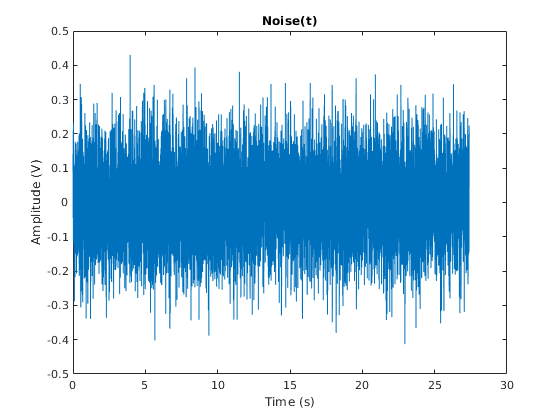

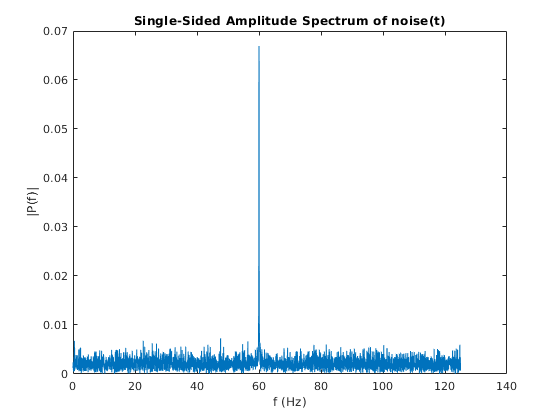

ans = 5.0142

case123=2; % modify this number and run simulation for cases 1, 2 and 3
% load('ecg.mat')
% ratio=10;
% ecg = decimate(ecg,ratio);
% 
% fs=2500/ratio;
load('ecg1.mat')
fs=250;
N=length(ecg);
T=1/fs;
t = (0:N-1)*T;  

if case123 == 1

elseif case123 ==2
    noise=additive_noise_model(N, fs, 'Gaussian', [0, 0.1], '60 Hz', [0.1], 'Plotting');
    ecg=ecg+noise;
    snr(ecg,noise)
elseif case123 ==3
    noise=additive_noise_model(N, fs, 'BandLimited Impulse', [2, 1, 10], 'Gaussian', [0, 0.01],'Plotting');
    ecg=ecg+noise;
    snr(ecg,noise)
end

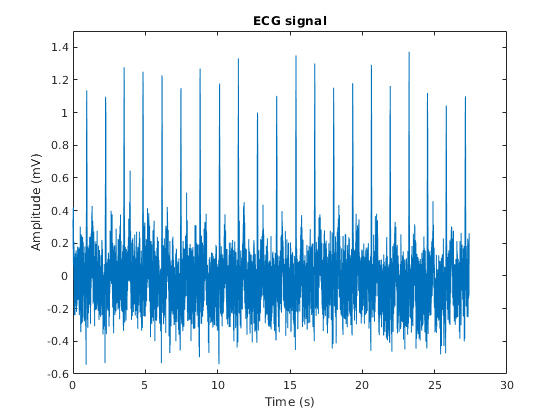


plot(t,ecg);
    title('ECG signal')
    xlabel('Time (s)')
    ylabel('Amplitude (mV)')
    ylim([-0.6,1.5])

    annonation_save('a)',"Fig7.7a.jpg", SAVE_FLAG);

## Offline algorithm for estimating heart rate

t=1/fs:1/fs:length(ecg)/fs;

Filtering

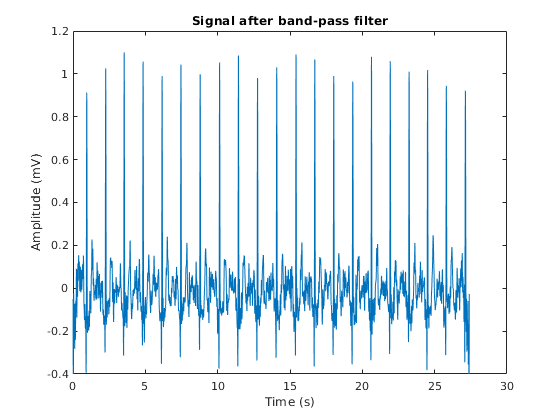

ecg_BP = bandpass(ecg,[1,20],fs);
% Plotting
figure
plot(t,ecg_BP)
xlabel('Time (s)');
ylabel('Amplitude (mV)');
ylim([-0.4,1.2])
title('Signal after band-pass filter');

annonation_save('b)',"Fig7.7b.jpg", SAVE_FLAG);


Differentiator

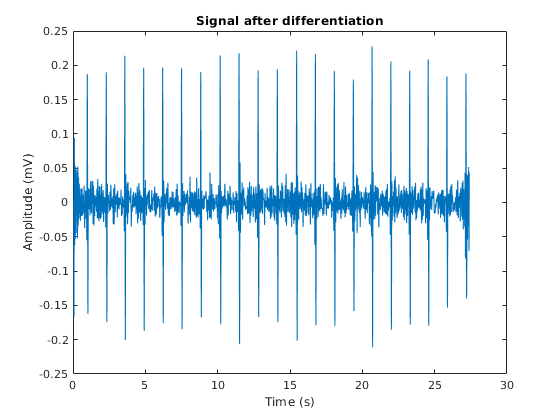

b = firls(30,[0 0.9],[0 0.9*pi],'differentiator');
%fvtool(b,1,'MagnitudeDisplay','zero-phase')
ecg_diff = filter(b,1,ecg_BP);

% Plotting
figure
plot(t,ecg_diff)
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Signal after differentiation');

annonation_save('c)',"Fig7.7c.jpg", SAVE_FLAG);

Absolute vaue or squaring

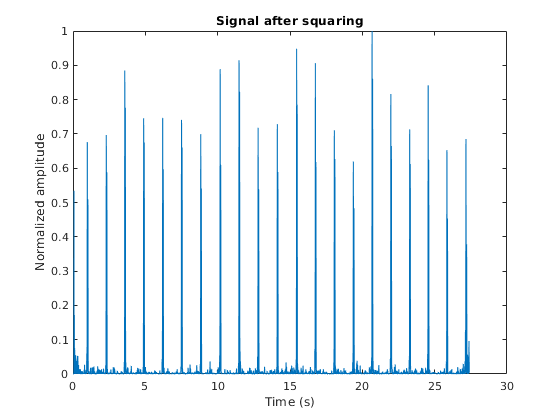

ecg_sq = ecg_diff.^2;
% Plotting
figure
plot(t,ecg_sq/max(ecg_sq))
xlabel('Time (s)');
ylabel('Normalized amplitude');
title('Signal after squaring');

annonation_save('d)',"Fig7.7d.jpg", SAVE_FLAG);

Time averaging

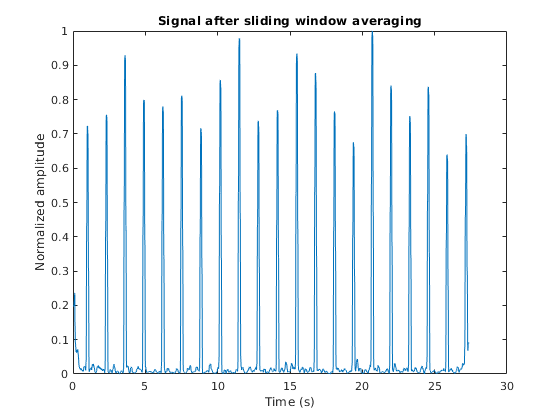

ecg_av=moving(ecg_sq,31); 
% Plotting
figure
plot(t,ecg_av/max(ecg_av))
xlabel('Time (s)');
ylabel('Normalized amplitude');
title('Signal after sliding window averaging');

annonation_save('e)',"Fig7.7e.jpg", SAVE_FLAG);

Presenting the digital pulses

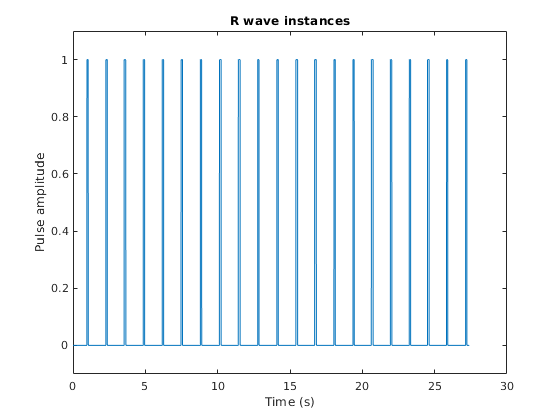

max_h = max(ecg_av);
thresh = max_h/2; %mean(ecg_av);
r_wave_instances =(ecg_av > thresh)';
% Plotting
figure
plot(t,r_wave_instances)
xlabel('Time (s)');
ylabel('Pulse amplitude');
title('R wave instances');
ylim([-.1, 1.1])

annonation_save('f)',"Fig7.7f.jpg", SAVE_FLAG);

Heart rate based on the number of pulses in the specific time interval

[dypks,ix] = findpeaks(double(r_wave_instances), 'MinPeakDistance',fs/2, 'MinPeakProminence',0.5);     % Zero-Crossings & Indices
heart_rate1=round(60*length(ix)/t(end));
X=['Heart rate based on the number of pulses in the specific time interval: ', num2str(heart_rate1), ' beats per min'];
disp(X)

Heart rate based on the number of pulses in the specific time interval: 46 beats per min


Heart rate based on the average RR interval

mean_RR=mean(diff(ix));
heart_rate2=round(60*fs/mean_RR);
X=['Heart rate based on the average RR interval: ', num2str(heart_rate2), ' beats per min'];
disp(X)

Heart rate based on the average RR interval: 46 beats per min


### Exersizes

Excersize 1: Estimate heart rate for the cases when ECG pulses are corrupted by noise. Comment on when the algorithm start failing

## Delineating the ECG signal

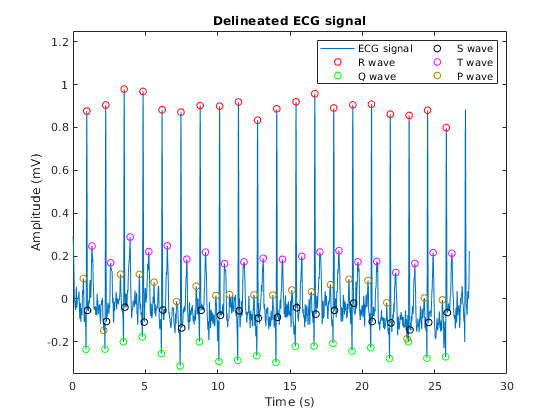

[R1,Q,S,T,P_w, Te, ecg1] = MTEO_qrst(ecg,fs,0);

figure,plot(t,ecg1);
hold on,scatter(R1(:,1)/fs,R1(:,2),'r');
hold on,scatter(Q(:,1)/fs,Q(:,2),'g');
hold on,scatter(S(:,1)/fs,S(:,2),'k');
hold on,scatter(T(:,1)/fs,T(:,2),'m');
hold on,scatter(P_w(:,1)/fs,P_w(:,2),'MarkerEdgeColor',[.7 .5 0]);
ylim([-0.35,1.25])
legend({'ECG signal','R wave','Q wave','S wave','T wave', 'P wave'},'NumColumns',2)
title('Delineated ECG signal')
xlabel('Time (s)')
ylabel('Amplitude (mV)')
exportgraphics(gcf,"Fig7.19.jpg", 'Resolution',600)